figure;
set(figure, 'Units', 'centimeters', 'Position', [5, 5, 18, 7.5]);

x = [0 0.2025 0.8082 1.8143 3.2171 5.0125 7.1960 9.7627 12.7069 16.0227...
    19.7039 23.7438 28.1353 32.8713 37.9440 41.1462 44.4814 45.8624 47.8143...
    50.5721 53.6854 54.4645];
y = [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.05 0.1 0.2 0.4 0.6 0.8];
z = [0 1.6183 3.2258 4.8202 6.3994 7.9613 9.5039 11.0255 12.5242 13.9985...
    15.4468 16.8677 18.2601 19.6227 20.9545 21.7385 22.7167 22.7167 22.7167...
    22.7167 22.7167 22.7167];
xo = [55 55 55.2 55.2]
yo = [0 0.7 0.7 0]
xo2 = [54.8 54.8 55.4 55.4]
yo2 = [0 0.1 0.1 0]

scatter(x, y, 20, z, 'fill', 'MarkerEdgeColor', 'black')
hold on
fill(xo, yo, 'black')
hold on
fill(xo2, yo2, 'black')
axis([0 70 0 3])
grid on;

cmap = colormap(flipud(autumn))
colormap(cmap)
c = colorbar('southoutside')
c.Label.String = 'Velocidade (m/s)';

xlabel('Comprimento de pista de decolagem (m)');
ylabel('Altura (m)');
text(0.02, 0.98, 'Peso da Aeronave = 22,4 kg', 'FontSize', 8, 'Color', [105/255, 105/255, 105/255], ...
     'Units', 'normalized', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'top');


set(gcf, 'PaperOrientation', 'landscape'); % Define a orientação como paisagem
set(gcf, 'PaperPositionMode', 'auto'); % Ajusta o gráfico na folha
print('Decolagem OK','-dpng','-r450')

figure;
set(figure, 'Units', 'centimeters', 'Position', [5, 5, 18, 7.5]);

x = [0 0.1802 0.7194 1.6153 2.8652 4.4661 6.4144 8.7064 11.3379 14.3045...
    17.6016 21.2239 25.1664 29.4234 33.9893 38.8582 44.0239 49.4802 53.8908...
    57.4312 58.8971 60.9694 63.8974 66.1415 68.0310]

z = [0 1.4402 2.8720 4.2937 5.7037 7.1008 8.4833 9.5779 10.9310 12.5306 ...
    13.8423 15.1333 16.4028 17.6499 18.8736 20.0733 21.2482 22.3979 23.0754...
    24.1138 24.1138 24.1138 24.1138 24.1138 24.1138]

y = [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.05 0.1 0.2 0.4 0.6 0.8]

xo = [55 55 55.2 55.2]
yo = [0 0.7 0.7 0]
xo2 = [54.8 54.8 55.4 55.4]
yo2 = [0 0.1 0.1 0]

scatter(x, y, 20, z, 'fill', 'MarkerEdgeColor', 'black')
hold on
fill(xo, yo, 'black')
hold on
fill(xo2, yo2, 'black')
axis([0 70 0 3])
grid on;

cmap = colormap(flipud(autumn))
colormap(cmap)
c = colorbar('southoutside')
c.Label.String = 'Velocidade (m/s)';

xlabel('Comprimento de pista de decolagem (m)');
ylabel('Altura (m)');
text(0.02, 0.98, 'Peso da Aeronave = 25,0 kg', 'FontSize', 8, 'Color', [105/255, 105/255, 105/255], ...
     'Units', 'normalized', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'top');


set(gcf, 'PaperOrientation', 'landscape'); % Define a orientação como paisagem
set(gcf, 'PaperPositionMode', 'auto'); % Ajusta o gráfico na folha
print('Decolagem NOK','-dpng','-r450')

### Melhor Indivíduo -> 20 kg

INPUT.world.gravity = 9.81;  %(m/s²)
INPUT.world.density = 1.108; %(kg/m³)
INPUT.world.friction = 0.04;
INPUT.decisions.TO_dist = 55; %(m)
INPUT.decisions.obstacle = 0.8; %(m)
INPUT.decisions.friction_drag = 0.016;
INPUT.decisions.wing_density = 1.5;

INPUT.design.chord_r = 0.384;
INPUT.design.taper = 0.402;
INPUT.design.span = 2.628;
INPUT.design.y_taper = 0.429;
INPUT.design.offset_tip = 0.053;
INPUT.design.twist_mid = -1.0;
INPUT.design.twist_tip = -1.0;
INPUT.design.airfoil = "UruA94113.dat";
INPUT.design.power_plant = [-0.0330 -0.4877 154.1342];

% DECLARAÇÃO DAS VARIÁVEIS:
c1 = INPUT.design.chord_r;
c2 = INPUT.design.chord_r * INPUT.design.taper;
b = INPUT.design.span/2;
b1 = b * INPUT.design.y_taper;
Sref = 2*((c1 * b1) + (((c1 + c2)*(b - b1))/2));

g = INPUT.world.gravity;
rho = INPUT.world.density;
mu = INPUT.world.friction;
Ta = INPUT.design.power_plant(1);
Tb = INPUT.design.power_plant(2);
Tc = INPUT.design.power_plant(3);
CD0 = INPUT.decisions.friction_drag;
h_o = INPUT.decisions.obstacle;

[OUTPUT] = AVL_RUN (INPUT);
CL = OUTPUT.AVL.CL;
CDi = OUTPUT.AVL.CDi;

m = 20;

% DEFINIÇÃO DAS VARIÁVEIS IMPORTANTES PARA O LOOP: 
v_x = 0; a_x = 0;                              % Velocidade-X em t=0.
vx_list = zeros(1,10); t_list = zeros(1,10);   % Listas de Armazenamento.
i = 1;                                         % Contador de Iterações.

% DEFINIÇÕES DA FORÇA PESO E DA SUSTENTAÇÃO:
W = m * g;                                     % Peso para determinado m.
L = 0;                                         % Sustentação em t=0.

% SIMULAÇÃO DA CORRIDA EM SOLO:
for t = 0 : 0.05 : 30
    if L <= W
        v0_x = v_x;                            % Velocidade-X em t-1.
        v_x = v0_x + a_x * 0.05;               % Velocidade-X em t.

        q = 0.5 * rho * (v_x)^2;               % Pressão dinâmica em t.
        T = (Ta * (v_x)^2) + (Tb * v_x) + Tc;  % Tração em t.
        D = q * Sref * (CD0 + CDi);            % Arrasto em t.
        L = q * Sref * CL;                     % Sustentação em t.
        R = mu * (W - L);                      % Atrito em t.

        a_x = (T - D - R)/m;                   % Aceleração-X em t.

        vx_list(i) = v_x;                      % Armezenamento de V_x.
        t_list(i) = t;                         % Armezenamento de t.
        i = i + 1;                           
    end
end

for i = 6 : 5 : 61
   trapz(t_list(1:end), vx_list(1:end)) 
end

% TRANSIÇÃO ATÉ ULTRAPASSAR O OBSTÁCULO:
tr_r = 0.2156 * ((1.045*v_x)^2);                % Raio de transição.
s_t = sqrt(tr_r^2 - (tr_r-0.8)^2);             % Distância - ultrapassagem.

s_tot = s_g + s_t                             % Distância total.

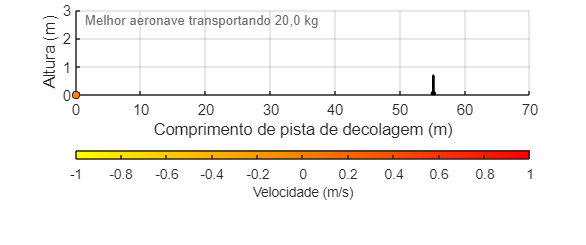

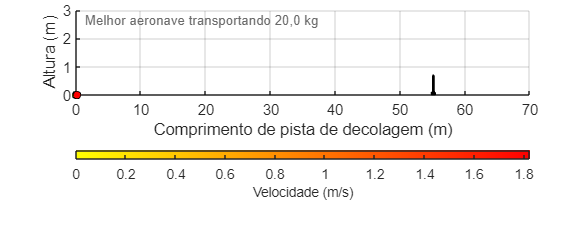

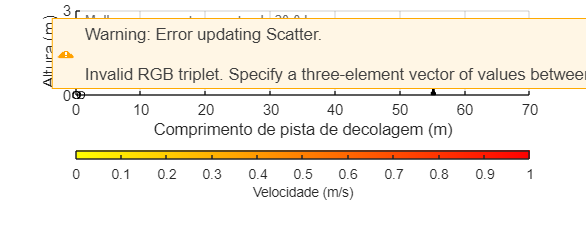

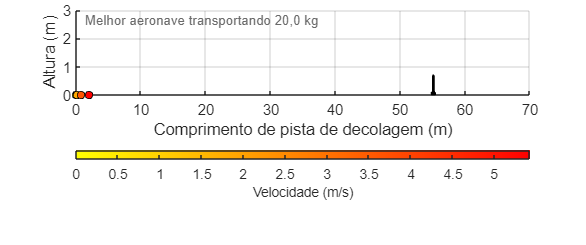

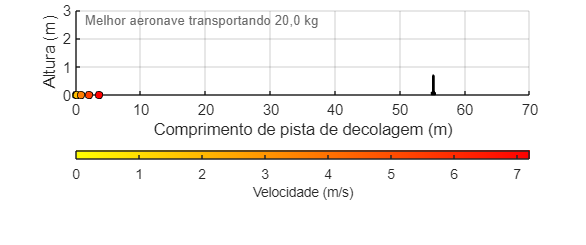

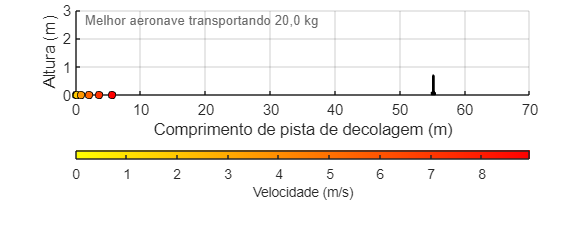

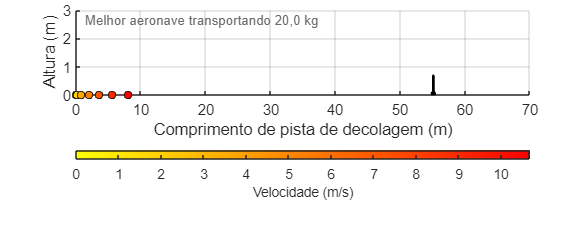

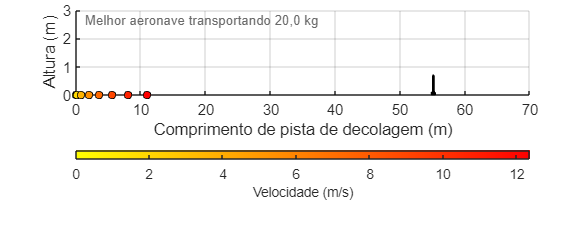

x = [0 0.2282 0.9107 2.0435 3.6219 5.6406 8.0934 10.9736 14.2739 17.9861 22.1020...
    26.6125 31.5084 32.5329 35.6997 37.0109 38.8642 41.4822 43.4880 45.1764];
z = [0 1.8237 3.6334 5.4259 7.1982 8.9474 10.6709 12.3661 14.0305 15.6622...
    17.2590 18.8193 20.3414 20.6412 21.5701 21.5701 21.5701 21.5701 21.5701 ...
    21.5701];
y = [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.05 0.1 0.2 0.4 0.6 0.8];
xo = [55 55 55.2 55.2];
yo = [0 0.7 0.7 0];
xo2 = [54.8 54.8 55.4 55.4];
yo2 = [0 0.1 0.1 0];
    
for i = 1 : 1 : 20
    figure;
    set(figure, 'Units', 'centimeters', 'Position', [5, 5, 18, 7.5]);
    
    scatter(x(1:i), y(1:i), 20, z(1:i), 'fill', 'MarkerEdgeColor', 'black')
    hold on
    fill(xo, yo, 'black')
    hold on
    fill(xo2, yo2, 'black')
    axis([0 70 0 3])
    grid on;
    
    cmap = colormap(flipud(autumn));
    colormap(cmap);
    c = colorbar('southoutside');
    c.Label.String = 'Velocidade (m/s)';
    
    xlabel('Comprimento de pista de decolagem (m)');
    ylabel('Altura (m)');
    text(0.02, 0.98, 'Melhor aeronave transportando 20,0 kg', 'FontSize', 8, 'Color', [105/255, 105/255, 105/255], ...
         'Units', 'normalized', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'top');
    
    p = "Plots\Velocity"+ i +".png";

    set(gcf, 'PaperOrientation', 'landscape'); % Define a orientação como paisagem
    set(gcf, 'PaperPositionMode', 'auto'); % Ajusta o gráfico na folha
    print(p,'-dpng','-r450')
end

### Pior Indivíduo -> 20 kg

INPUT.world.gravity = 9.81;  %(m/s²)
INPUT.world.density = 1.108; %(kg/m³)
INPUT.world.friction = 0.04;
INPUT.decisions.TO_dist = 55; %(m)
INPUT.decisions.obstacle = 0.8; %(m)
INPUT.decisions.friction_drag = 0.016;
INPUT.decisions.wing_density = 1.5;

INPUT.design.chord_r = 0.384;
INPUT.design.taper = 0.402;
INPUT.design.span = 2.628;
INPUT.design.y_taper = 0.429;
INPUT.design.offset_tip = 0.053;
INPUT.design.twist_mid = -1.0;
INPUT.design.twist_tip = -1.0;
INPUT.design.airfoil = "UruA94113.dat";
INPUT.design.power_plant = [-0.0330 -0.4877 154.1342];

% DECLARAÇÃO DAS VARIÁVEIS:
c1 = INPUT.design.chord_r;
c2 = INPUT.design.chord_r * INPUT.design.taper;
b = INPUT.design.span/2;
b1 = b * INPUT.design.y_taper;
Sref = 2*((c1 * b1) + (((c1 + c2)*(b - b1))/2));

g = INPUT.world.gravity;
rho = INPUT.world.density;
mu = INPUT.world.friction;
Ta = INPUT.design.power_plant(1);
Tb = INPUT.design.power_plant(2);
Tc = INPUT.design.power_plant(3);
CD0 = INPUT.decisions.friction_drag;
h_o = INPUT.decisions.obstacle;

[OUTPUT] = AVL_RUN (INPUT);
CL = OUTPUT.AVL.CL;
CDi = OUTPUT.AVL.CDi;

m = 20;

% DEFINIÇÃO DAS VARIÁVEIS IMPORTANTES PARA O LOOP: 
v_x = 0; a_x = 0;                              % Velocidade-X em t=0.
vx_list = zeros(1,10); t_list = zeros(1,10);   % Listas de Armazenamento.
i = 1;                                         % Contador de Iterações.

% DEFINIÇÕES DA FORÇA PESO E DA SUSTENTAÇÃO:
W = m * g;                                     % Peso para determinado m.
L = 0;                                         % Sustentação em t=0.

% SIMULAÇÃO DA CORRIDA EM SOLO:
for t = 0 : 0.05 : 30
    if L <= W
        v0_x = v_x;                            % Velocidade-X em t-1.
        v_x = v0_x + a_x * 0.05;               % Velocidade-X em t.

        q = 0.5 * rho * (v_x)^2;               % Pressão dinâmica em t.
        T = (Ta * (v_x)^2) + (Tb * v_x) + Tc;  % Tração em t.
        D = q * Sref * (CD0 + CDi);            % Arrasto em t.
        L = q * Sref * CL;                     % Sustentação em t.
        R = mu * (W - L);                      % Atrito em t.

        a_x = (T - D - R)/m;                   % Aceleração-X em t.

        vx_list(i) = v_x;                      % Armezenamento de V_x.
        t_list(i) = t;                         % Armezenamento de t.
        i = i + 1;                           
    end
end

for i = 6 : 5 : 61
   trapz(t_list(1:end), vx_list(1:end)) 
end

% TRANSIÇÃO ATÉ ULTRAPASSAR O OBSTÁCULO:
tr_r = 0.2156 * ((1.045*v_x)^2);                % Raio de transição.
s_t = sqrt(tr_r^2 - (tr_r-0.8)^2);             % Distância - ultrapassagem.

s_tot = s_g + s_t                             % Distância total.

x = [0 0.2282 0.9107 2.0435 3.6219 5.6406 8.0934 10.9736 14.2739 17.9861 22.1020...
    26.6125 31.5084 32.5329 35.6997 37.0109 38.8642 41.4822 43.4880 45.1764];
z = [0 1.8237 3.6334 5.4259 7.1982 8.9474 10.6709 12.3661 14.0305 15.6622...
    17.2590 18.8193 20.3414 20.6412 21.5701 21.5701 21.5701 21.5701 21.5701 ...
    21.5701];
y = [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0.05 0.1 0.2 0.4 0.6 0.8];
xo = [55 55 55.2 55.2];
yo = [0 0.7 0.7 0];
xo2 = [54.8 54.8 55.4 55.4];
yo2 = [0 0.1 0.1 0];
    
for i = 1 : 1 : 20
    figure;
    set(figure, 'Units', 'centimeters', 'Position', [5, 5, 18, 7.5]);
    
    scatter(x(1:i), y(1:i), 20, z(1:i), 'fill', 'MarkerEdgeColor', 'black')
    hold on
    fill(xo, yo, 'black')
    hold on
    fill(xo2, yo2, 'black')
    axis([0 70 0 3])
    grid on;
    
    cmap = colormap(flipud(autumn));
    colormap(cmap);
    c = colorbar('southoutside');
    c.Label.String = 'Velocidade (m/s)';
    
    xlabel('Comprimento de pista de decolagem (m)');
    ylabel('Altura (m)');
    text(0.02, 0.98, 'Melhor aeronave transportando 20,0 kg', 'FontSize', 8, 'Color', [105/255, 105/255, 105/255], ...
         'Units', 'normalized', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'top');
    
    p = "Plots\Velocity"+ i +".png";

    set(gcf, 'PaperOrientation', 'landscape'); % Define a orientação como paisagem
    set(gcf, 'PaperPositionMode', 'auto'); % Ajusta o gráfico na folha
    print(p,'-dpng','-r450')
end